# Calling the `ode45` function

## Task 1

You need to solve the ODE over the interval t=0to t=4*π*. Create a two-element row vector `tRange` to represent this time interval. 

 Use the built-in MATLAB variable `pi` to represent the number *π*

tRange=[0 4*pi]

tRange =          0   12.5664


## Task 2

Create a variable `y0` and assign to it the value of the initial condition, `0`.

y0=0

y0 = 0

## Task 3

The `ode45` function has the following syntax:

`[``t``,``y``]` `=` `ode45``(``@``funcname``,``tspan``,``y0``)`

Task

Use `ode45` to solve the ODE.

The ODE function has been defined for you in the local function `myTrigODE` at the bottom of the script. `tRange` contains the time interval, and `y0` contains the initial condition. 

Use `tSol` and `ySol` as your output variables.

[tSol,ySol]=ode45(@myTrigODE,tRange,y0)

tSol =          0
    0.3142
    0.6283
    0.9425
    1.2566
    1.5708
    1.8850
    2.1991
    2.5133
    2.8274


ySol =          0
    0.0491
    0.1910
    0.4121
    0.6910
    1.0002
    1.3091
    1.5876
    1.8090
    1.9511


## Task 4

Plot your solution `ySol` as a function of `tSol` using a dashed line (`"--"`).

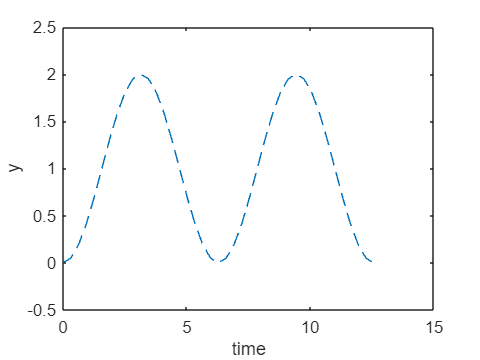

plot(tSol,ySol,"--")
% Label axes
xlabel("time")
ylabel("y")

## Further Practice

The exact solution to the ODE solved here is y=1−cos(t). Try plotting the exact solution on the same figure as your numerical solution to see if they agree.

`tExact` `=` `linspace``(``0``,``4``*``pi``,``40``)``;`

`yExact` `=` `1` `-` `cos``(``tExact``)``;`

`hold` `on` 

`plot``(``tExact``,``yExact``,``"m:o"``)``;`

`hold` `off`

`legend``(``"ode45"``,``"exact"``)`

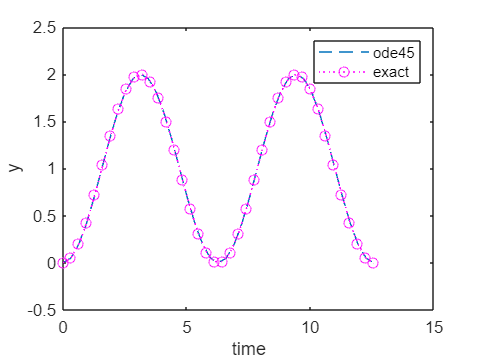

tExact = linspace(0,4*pi,40);
yExact = 1 - cos(tExact);
hold on 
plot(tExact,yExact,"m:o");
hold off
legend("ode45","exact")

Do not edit. This code defines the ODE function to solve the ODE  .

function dydt = myTrigODE(t,y)
% Define dydt:
dydt = sin(t);
end